# 4-3

## a

clc;
clear all;

In this part we perform 2D wavelet transform to the image to see the result. Then we highlight the edges using wavelet transform.

after performing 'db1' wavelet transform we reach to 4 coefficient.

- `cA`: It stands for Approximation coefficients at a coarser scale. It represents the low-frequency components or the approximation of the original signal or image after performing the 2D DWT. The `cA` coefficients capture the coarse details of the signal or image.

- `cH`: It represents the Horizontal detail coefficients. These coefficients capture the high-frequency details in the horizontal direction after performing the 2D DWT. They provide information about the horizontal edges or features in the signal or image.

- `cV`: It represents the Vertical detail coefficients. These coefficients capture the high-frequency details in the vertical direction after performing the 2D DWT. They provide information about the vertical edges or features in the signal or image.

- `cD`: It represents the Diagonal detail coefficients. These coefficients capture the high-frequency details in the diagonal direction after performing the 2D DWT. They provide information about the diagonal edges or features in the signal or image.


x1=imread("Image03.jpg");
x1 = im2double(x1);
[cA,cH,cV,cD] = dwt2(x1,'db1');
cH = imresize(cH,2);
cH(:,:,2) =0;
cH(:,:,3) =0;
aa=size(x1);
cH= cH(1:aa(1),1:aa(2),:);
size(cH);
size(x1);
highlighted = 0.5*x1 + 10*cH;


### The result is:

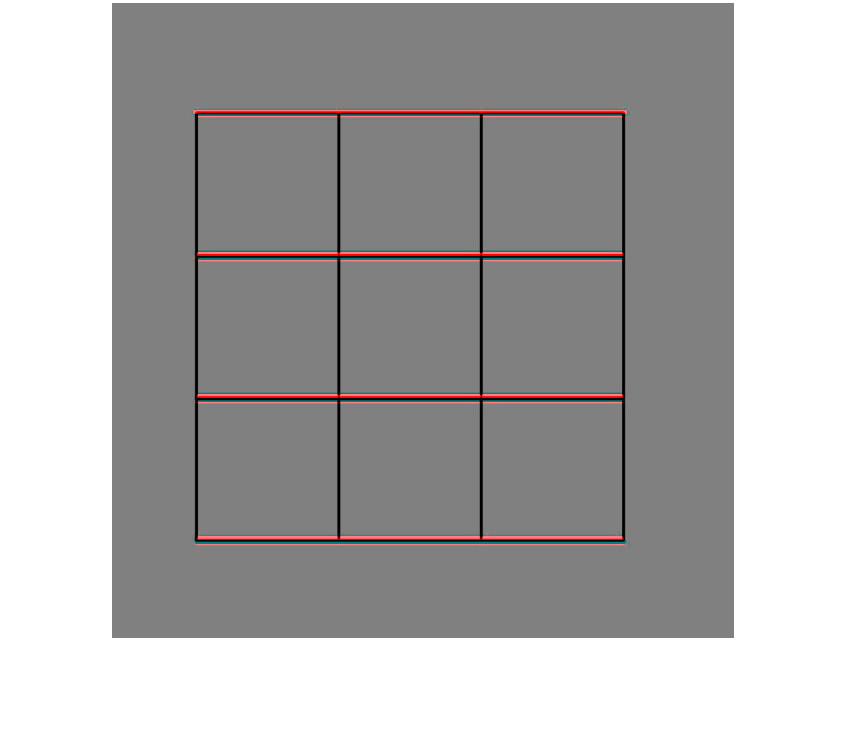

figure()
imshow(highlighted);
title("Horizontal lines");

# Blurring

One of the challenges of photography is blurring of images. This happens when the object is moving when the camera shutter is open. We can correct it with the knowledge of the pattern of the body.

First we start our work with performing blurring to our given image. This is done with defining a kernel for motion blurr using fspecial('motion' , 15, 20) function. Here we set our blurr to be of size 15 and angel 15 degrees.

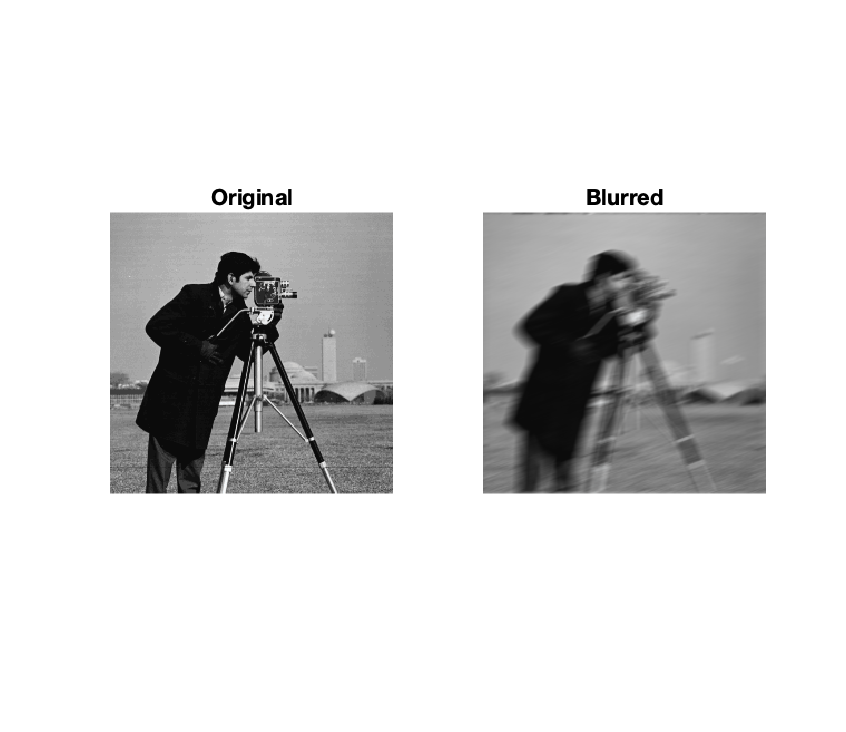

h= fspecial('motion',15,20);
x1=imread("Image04.png");
x1=im2double(x1);
blurred=imfilter(x1,h,'conv','circular');
subplot(1,2,1)
imshow(x1);
title('Original')
subplot(1,2,2)
imshow(blurred);
title('Blurred')

Next we use deconvwnr() for the purpose of removing the Blurring effect. 

Deblur image using Wiener filter J = deconvwnr(I,PSF,NSR) deconvolves image I using the Wiener filter algorithm, returning deblurred image J. Image I can be an N-dimensional array. PSF is the point-spread function with which I was convolved. NSR is the noise-to-signal power ratio of the additive noise. NSR can be a scalar or a spectral-domain array of the same size as I. Specifying 0 for the NSR is equivalent to creating an ideal inverse filter. The algorithm is optimal in a sense of least mean square error between the estimated and the true images. 

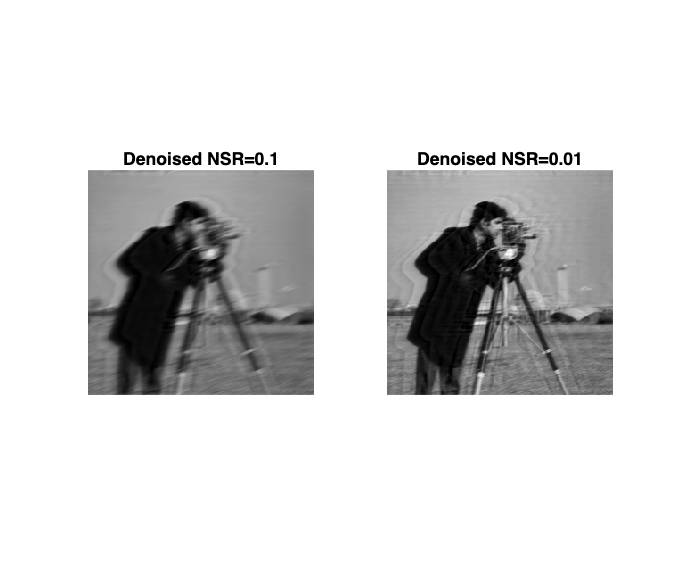

x_denoised2=deconvwnr(blurred,h,0.1);
subplot(1,2,1)
imshow(x_denoised2)
title("Denoised NSR=0.1")

x_denoised1=deconvwnr(blurred,h,0.01);
subplot(1,2,2)
imshow(x_denoised1)
title("Denoised NSR=0.01")

### Next we add a gaussian noise with zero mean and standard variance of 10 to our blurred image using imnoise() function

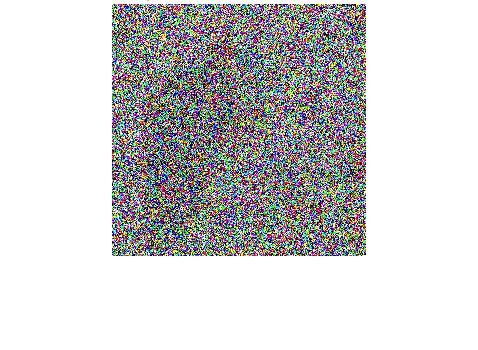

Gaussian_noise=imnoise(blurred,'gaussian',0,10);
subplot(1,1,1)
imshow(Gaussian_noise)
title("Blurred image added with Gaussian noise")

Now we perform deconvwr() to the blurred image added with Gaussian noise. As we see, the result image has no content at all.

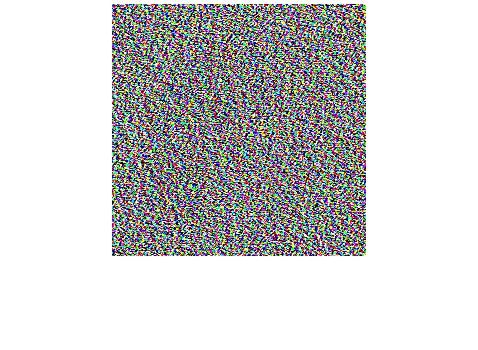

subplot(1,1,1)
imshow(deconvwnr(Gaussian_noise,h,0.01))
title("Denoised")

# Antialiasing

First we import glass.tif file and then using imshow(), it is illustrated.

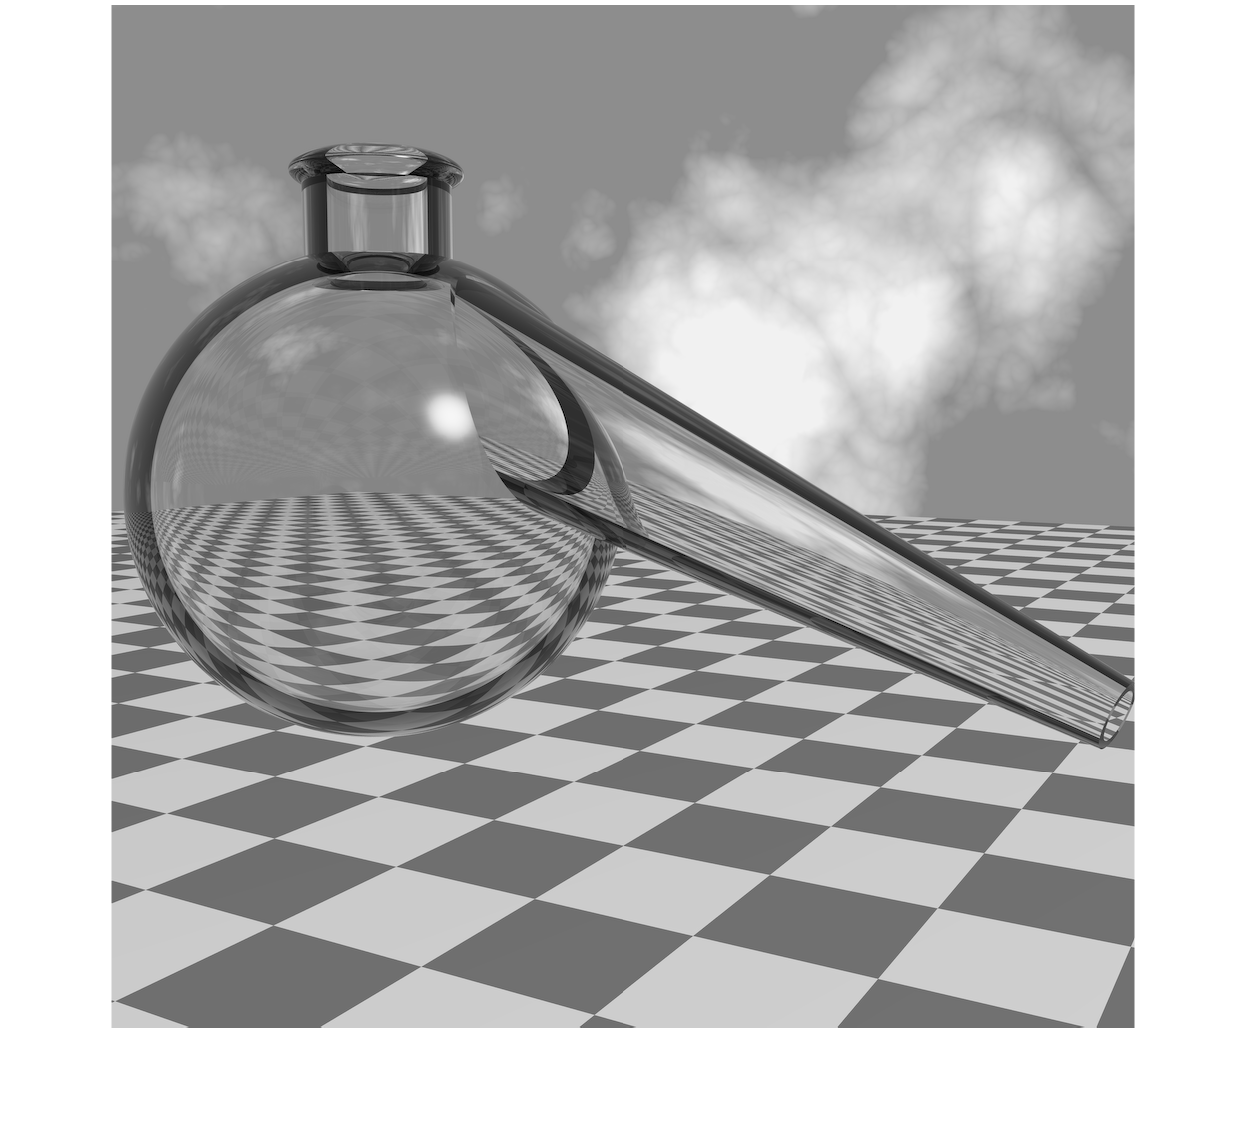

glass=imread("glass.tif");
glass=im2double(glass);
figure;
imshow(glass);

### 2D DFT of image

In the context of the `fft2` function, the `fftshift` function is used to rearrange the output of the 2D Fourier Transform (`fft2`) to shift the zero-frequency component (DC component) to the center of the spectrum.

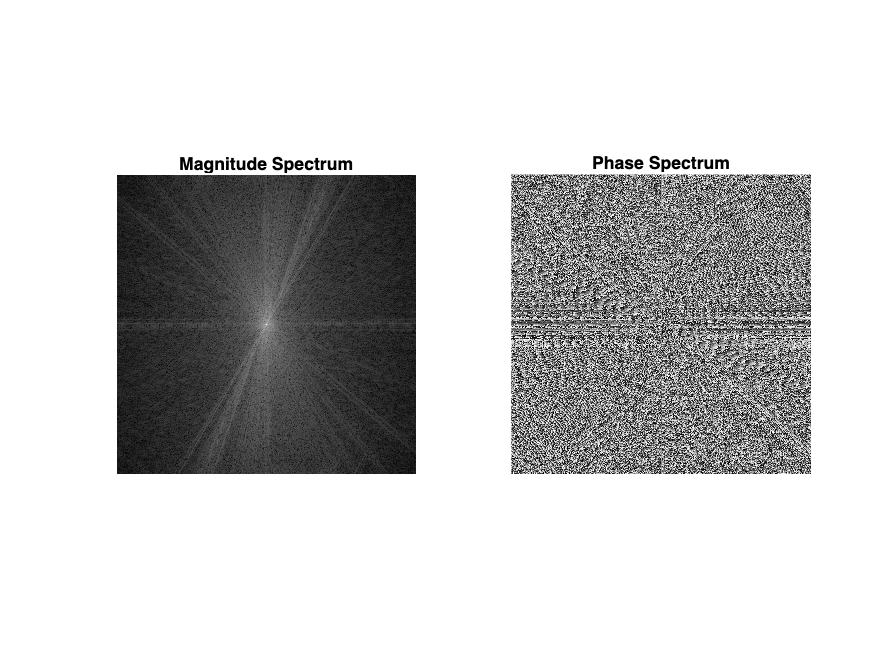

glass_dft=fftshift(fft2(glass)); %2D DFT
figure;
subplot(1,2,1)
imshow(log(1 + abs(glass_dft)), []);
title('Magnitude Spectrum');
subplot(1,2,2)
imshow(angle(glass_dft), []);
title('Phase Spectrum');

# FFT_LP_2D

### We are going to define a function for lowpass 2D filter. 

First we are going to import our desired image and then perform designed filter on our image with this specifications.

- Cutoff_frequency=0.1

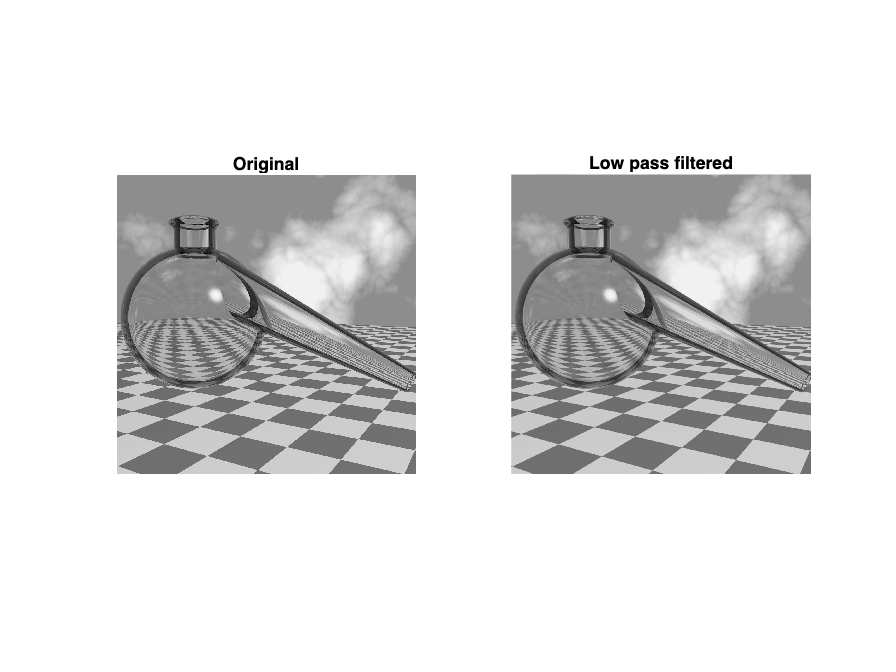

glass=imread("glass.tif");
glass=im2double(glass);
glass_lp=FFT_LP_2D(glass,0.1*pi);
figure;
subplot(1,2,1)
imshow(glass)
title('Original')
subplot(1,2,2)
imshow(glass_lp)
title('Low pass filtered');

The performance of a 2D low-pass filter on an image depends on the specific characteristics of the image and the cutoff frequency chosen for the filter. Here are some general observations:

- Smoothing/Blurring:

Low-pass filters are designed to attenuate high-frequency components in an image, which correspond to details and edges.

As you increase the cutoff frequency, more high-frequency components are attenuated, leading to increased smoothing or blurring of the image.

- Noise Reduction:

Low-pass filters can help reduce high-frequency noise in an image. This is particularly useful in situations where the image has been corrupted by random noise.

- Detail Preservation:

Lower cutoff frequencies preserve more details in the image, but they also allow more noise and fine details to remain.

Higher cutoff frequencies result in more aggressive smoothing, which may lead to a loss of fine details.

- Edge Preservation:

Low-pass filters, especially those applied in the frequency domain (like the FFT-based low-pass filter), tend to blur edges in the image.

This blurring can be beneficial in some cases (e.g., noise reduction) but may not be desirable if preserving sharp edges is important.

# Down Sampling

Here we use downsample function to see the alliasing effect of this function in edges of the image. Then, we perform designed lowpass filter to downsampled image to see the effect.

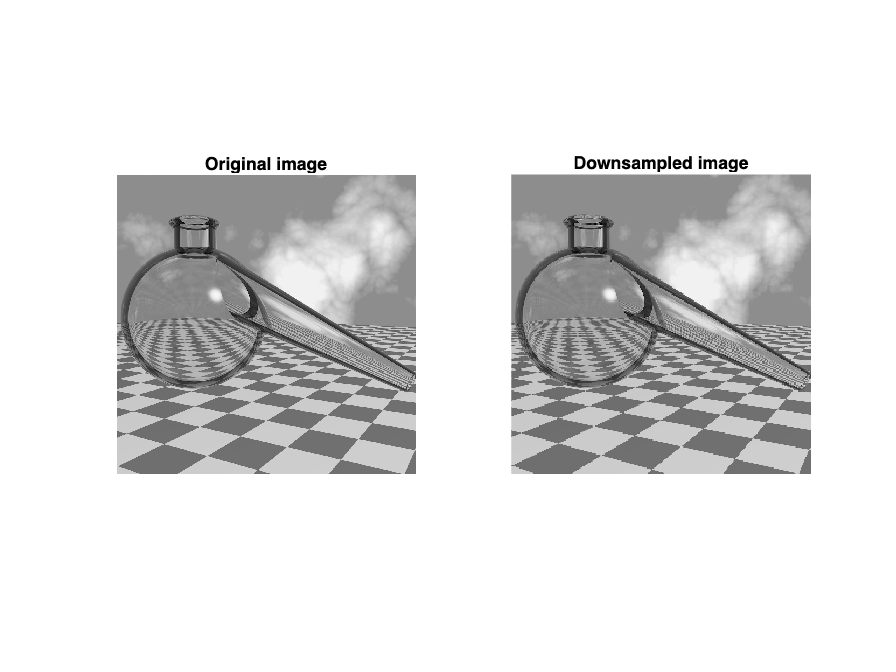

[height, width, ~] = size(glass);
downsamplingFactor = 4;
downsampled_image = imresize(glass, 1/downsamplingFactor, 'nearest');

figure;
subplot(1,2,1)
imshow(glass);
title('Original image');
subplot(1,2,2)
imshow(downsampled_image);
title('Downsampled image');

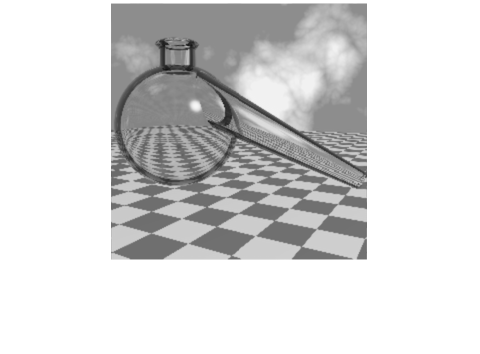

final=FFT_LP_2D(downsampled_image,0.1*pi);
figure
imshow(final);
title(' Fc=0.1*pi')

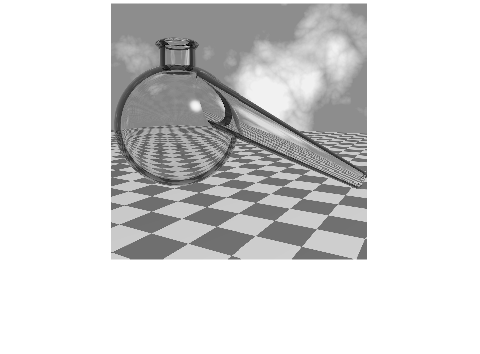

final2=FFT_LP_2D(downsampled_image,0.5*pi);
figure
imshow(final2);
title(' Fc=0.5*pi')

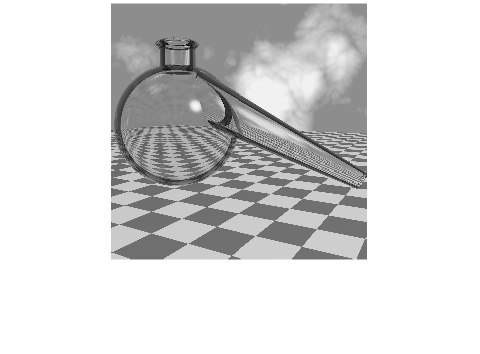

final3=FFT_LP_2D(downsampled_image,1*pi);
figure
imshow(final3);
title(' Fc=pi')

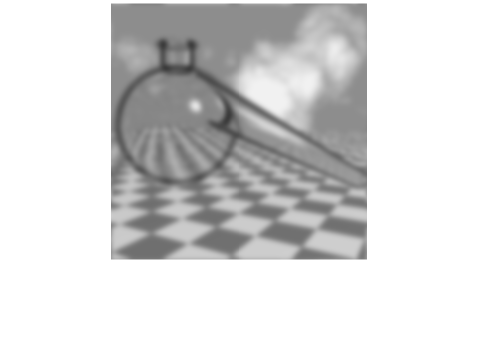

final4=FFT_LP_2D(downsampled_image,0.02*pi);
figure
imshow(final4);
title(' Fc=0.02*pi')

function output = FFT_LP_2D(input_im, cutoff_freq)
 
    % Get the size of the input image
    [M, N] = size(input_im);

    % Calculate the frequency domain coordinates
    dx = 1;
    dy = 1;
    KX0 = fftshift(mod((1/2 + (0:(N-1))/N), 1) - 1/2);
    KY0 = fftshift(mod((1/2 + (0:(M-1))/M), 1) - 1/2);

    % Create a 2D meshgrid of frequency domain coordinates
    [KX, KY] = meshgrid(KX0, KY0);

    % Create a low-pass filter in the frequency domain
    H = exp(-((KX * dx).^2 + (KY * dy).^2) / (2 * cutoff_freq^2));

    % Apply the filter in the frequency domain using FFT
    F = fftshift(fft2(input_im));
    F_filtered = F .* H;

    % Inverse FFT to get the filtered image in spatial domain
    output = real(ifft2(ifftshift((F_filtered)),'symmetric'));

    
end
